clear all;
the = [3.0000   0.0032  954.0000];
exp = [3.0060   0.0032 945.0000];
ink("He")

He


data1The = ...
    [0	400	800	1200	1600	2000	2400	2800	inf;
     0   886e-3  1.37    1.67    1.88    2.03    2.15    2.24    3;
     2.55e-3 2.22e-3 1.71e-3 1.29e-3 1.17e-3 1.02e-3 895e-6  799e-6  0;]

data1The = 	1.0e+03 *

         0    0.4000    0.8000    1.2000    1.6000    2.0000    2.4000    2.8000       Inf
         0    0.0009    0.0014    0.0017    0.0019    0.0020    0.0022    0.0022    0.0030
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0


data1 = data1The;
data2 = [0	400	800	1200	1600	2000	2400	2800	inf;
        3.00E-02	0.909	1.387	1.69	1.895	2.047	2.163	2.251	3.006;
        3.00E-03	2.21E-03	1.63E-03	1.34E-03	1.14E-03	9.87E-04	8.73E-04	7.83E-04	0.00E+00;
        1.00E+01	4.11E+02	8.51E+02	1.26E+03	1.67E+03	2.07E+03	2.48E+03	2.87E+03	inf;
        1.00E+01	409	8.06E+02	1.21E+03	1.61E+03	2.01E+03	2.41E+03	2.81E+03	nan;];
%[RL; VL; IL; RCalculate; RMeausre;] orginal circuit measurement

data3 = [0	400	800	1200	1600	2000	2400	2800	inf;
        0.028	0.903	1.378	1.682	1.888	2.04	2.156	2.245	3.008;
        2.84E-03	2.06E-03	1.62E-03	1.33E-03	1.13E-03	9.84E-04	8.71E-04	7.81E-04	0;
        9.86E+00	4.38E+02	8.50E+02	1.26E+03	1.67E+03	2.07E+03	2.48E+03	2.87E+03	inf;]; 
%[RL, VL, IL, Rcalcualted] Thevenin circuit

data4 = [0	400	800	1200	1600	2000	2400	2800	inf;
        2.00E-03	0.806	1.244	1.523	1.708	1.85	1.953	2.033	0.1;
        2.60E-03	1.88E-03	1.48E-03	1.21E-03	1.03E-03	8.96E-04	7.92E-04	7.10E-04	0.00E+00;
        7.70E-01	4.29E+02	8.42E+02	1.25E+03	1.66E+03	2.06E+03	2.47E+03	2.86E+03	inf;
        1.00E+01	409	8.06E+02	1.21E+03	1.61E+03	2.01E+03	2.41E+03	2.81E+03	nan;];
%[RL, VL, IL, Rcalculated] Norton Results

data5 = [   -953	    -350	    -150	    -50	        0	        50	        150	        350	        inf;
        3.80E-03	1.16E+00	1.372	    1.46	    1.501	    1.542	    1.613	    1.737	    3;
        3.14E-03	1.83E-03	1.63E-03	1.55E-03	1.51E-03	1.47E-03	1.40E-03	1.28E-03	0.00E+00;
        1.19E-05	2.12E-03	2.24E-03	2.26E-03	2.26E-03	2.26E-03	2.25E-03	2.22E-03	0.00E+00;];
% [DeltaR; VL; IL, PL;]

reE(data5(3,:), data5(4,:))% testing the functionaliy of reE

ans = 	1.0e+04 *

    2.6287   -0.0014   -0.0027   -0.0031   -0.0033   -0.0035   -0.0038   -0.0042       NaN


abE(data5(3,:), data5(4,:))

ans =     0.0031   -0.0003   -0.0006   -0.0007   -0.0007   -0.0008   -0.0008   -0.0009         0


% result quite good to use

ink("What should we do next?")

What should we do next?


ink("I have no ideal....")

I have no ideal....


ink("...")

...


ink("this feeling is terrible")

this feeling is terrible



ink("lets draw some diagrams!")

lets draw some diagrams!


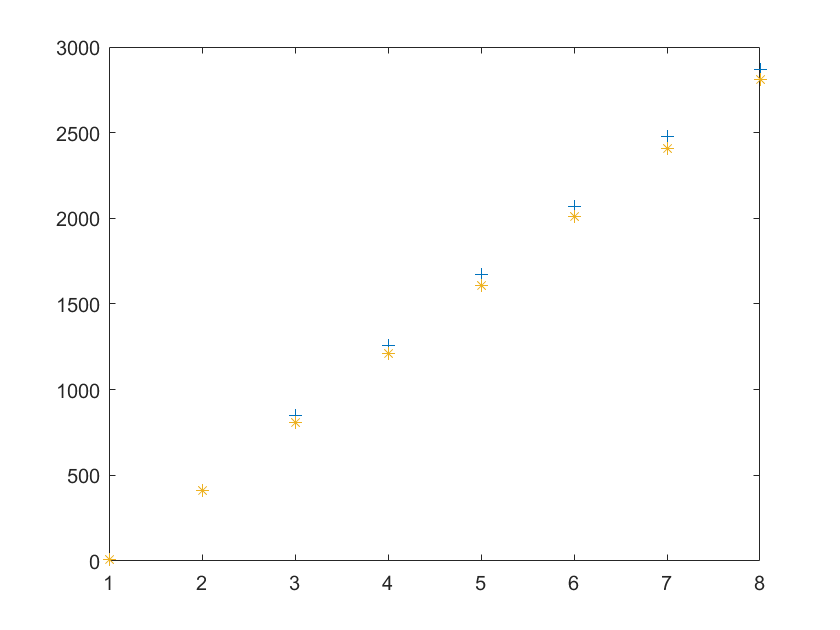

[~,c] = size(data2);
axis = 1:c;
x = axis;
RMeasured = data2(4,:);
y1 = RMeasured;
RCalculated = data2(5,:);
y2 = RCalculated;
x2 = 1:0.01:c;
p  = polyfit(x,y1,4);
      Y= polyval(p,x2);
plot(x,y1,'+',x2,Y,'')
hold on
p1= polyfit(x,y2,4);
      Y1= polyval(p1,x2);
plot(x,y2,'*',x2,Y1,'k')



%lets draw the measured R and calculated R
titles = ["RL", "VL theo", "VL exp", "rel error %", "IL mA theo", "IL mA exp", "relError"]

titles = 1×7 string 数组
    "RL"    "VL theo"    "VL exp"    "rel error %"    "IL mA theo"    "IL mA exp"    "relError"


nameOfXls = "original Equivalent Circuit Processsed Data";
[~,c] = size(data2);
r = 7;
ShowData = zeros(r,c);
showData(1,:) = data1(1, :);%RL
showData(2,:) = data1(2, :);%Theo vl
showData(3,:) = data2(2, :);%exp Vl
showData(4,:) = reE(showData(3,:), showData(2,:));%rel Errror vl
showData(5,:) = data1(3, :)*1000;%theo error
showData(6,:) = data2(3, :)*1000;%exp current
showData(7,:) = reE(showData(6,:), showData(5,:));%rel error
fileName = nameOfXls;
RowDataCollections = showData;
rowDataNum = r;
RDatasToXls(titles, RowDataCollections, rowDataNum, fileName);

% the Thevenin Version
titles = ["RL", "VL theo", "VL exp", "rel error %", "IL mA theo", "IL mA exp", "relError"]

titles = 1×7 string 数组
    "RL"    "VL theo"    "VL exp"    "rel error %"    "IL mA theo"    "IL mA exp"    "relError"


nameOfXls = "Thevenin Equivalent Circuit Processsed Data";
[~,c] = size(data3);
r = 7;
ShowData = zeros(r,c);
showData(1,:) = data1(1, :);%RL
showData(2,:) = data1(2, :);%Theo vl
showData(3,:) = data3(2, :);%exp Vl
showData(4,:) = reE(showData(3,:), showData(2,:));%rel Errror vl
showData(5,:) = data1(3, :)*1000;%theo error
showData(6,:) = data3(3, :)*1000;%exp current
showData(7,:) = reE(showData(6,:), showData(5,:));%rel error
fileName = nameOfXls;
RowDataCollections = showData;
rowDataNum = r;
RDatasToXls(titles, RowDataCollections, rowDataNum, fileName);

% the Norton Version
titles = ["RL", "VL theo", "VL exp", "rel error %", "IL mA theo", "IL mA exp", "relError"]

titles = 1×7 string 数组
    "RL"    "VL theo"    "VL exp"    "rel error %"    "IL mA theo"    "IL mA exp"    "relError"


nameOfXls = "Norton Equivalent Circuit Processsed Data";
[~,c] = size(data3);
r = 7;
ShowData = zeros(r,c);
showData(1,:) = data1(1, :);%RL
showData(2,:) = data1(2, :);%Theo vl
showData(3,:) = data3(2, :);%exp Vl
showData(4,:) = reE(showData(3,:), showData(2,:));%rel Errror vl
showData(5,:) = data1(3, :)*1000;%theo error
showData(6,:) = data3(3, :)*1000;%exp current
showData(7,:) = reE(showData(6,:), showData(5,:));%rel error
fileName = nameOfXls;
RowDataCollections = showData;
rowDataNum = r;
RDatasToXls(titles, RowDataCollections, rowDataNum, fileName);

ink("Lets do the final part, cllect the PL data")

Lets do the final part, cllect the PL data


titles = ["delta R", "theo PL (mW)", "exp PL (mW)", "rel. Error"];
[~, c] = size(data5);
r = 4;
showData = zeros(r,c);
showData(1,:) = data5(1,:);
showData(2,:) = 1000* [0.0, 0.0022415097706200726, 0.0023437378386372007, 0.0023592519136444706, 0.00236096537250787, 0.0023594226354021605, 0.0023483985374494693, 0.002304139316432775, 8.997428453240388e-07];
showData(3,:) = 1000*data5(4,:);
showData(4,:) = reE(showData(3,:), showData(2,:));
fileName = "power maximum";
RowDataCollections = showData;
rowDataNum = r;
RDatasToXls(titles, RowDataCollections, rowDataNum, fileName);


function relError = reE(dataMeasure, dataCompare)
    [m,n] = size(dataMeasure);
    if [m,n] == size(dataCompare)
        % this function only deal with the first row's data
        dataOutput = zeros(m,n);
        for i = 1:n
            dataM = dataMeasure(1,i);
            dataC = dataCompare(1,i);
            dataOutput(1,i) = 100*(dataM-dataC)/dataC;
        end
        relError = dataOutput;
    end
end

% calculate the relavent error/difference between the Measured data and
% the comparison data, the scale is % -> 100 means 2times larger than the
% compare data
%
function absError = abE(dataMeasure, dataCompare)
    [m,n] = size(dataMeasure);
    if [m,n] == size(dataCompare)
        dataOutput = zeros(m,n);
        for i = 1:n
            dataM = dataMeasure(1,i);
            dataC = dataCompare(1,i);
            dataOutput(1,i) = dataM-dataC;
        end
        absError = dataOutput;
    end
end

% calculate the absoulute error/difference between the Measured data and
% the comparison data
%

function ink(words)
    fprintf(words);
    fprintf("\n");
end
%print out words in the terminal

function WriteOver = RDatasToXls(titles, RowDatasCollection, rowDataNum,fileName)
    %row Data Collections contains  rowindex col 2 dimmensions
    datas = RowDatasCollection(1:rowDataNum,:)';
    [m,n] = size(datas);
    data_cell = mat2cell(datas, ones(m,1), ones(n,1));
    ans = [titles; data_cell];
    WriteOver = xlswrite(fileName, ans);
end
%titles = [titleForRow1 "titleforrow2" ...]             RowDataCollection =
%[datainRow1;datainRow2; ...;], 
% %rowDataNum = number of the row of data to be transferred into xls files
%fileName = "The name of the xls file"